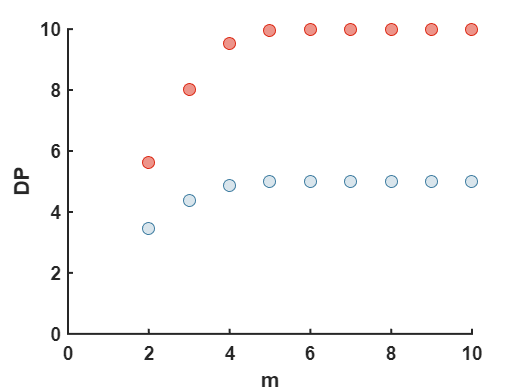

%考察笼腔内可容纳盖子数目m对互锁聚合度的影响
clear all 
syms p m y r q k a1 a2 a3 t;

a1=[];
a2=[];
a3=[];

hold on
axis([0 10 0 10]);

p=0.9; % p为互锁转化率
    for m=2:1:10 % m为一个笼腔内最多可容纳的盖子数
        for k=1:1:m-1
            t=(k+1)/(3*k-1);
            a1=[a1,t];
        end
        q=1-((m+1)/(3*m-1)); %1-q为前体结构进一步形成闭锁的概率
        r=1-(prod(a1)); %1-r为形成闭锁结构前驱体的概率
        y=(1-(p^(m+1))*(1-q)*(1-r))/(1-p);
        scatter(m,y, ...
            'markerfacecolor',[221, 42, 22]/256, ...
            'markeredgecolor',[221, 42, 22]/256, ...
            'markerfacealpha',0.5)
    end

p=0.8;
    for m=2:1:10
        for k=1:1:m-1
            t=(k+1)/(3*k-1);
            a2=[a2,t];
        end
        q=1-((m+1)/(3*m-1));
        r=1-(prod(a2));
        y=(1-(p^(m+1))*(1-q)*(1-r))/(1-p);
        scatter(m,y, ...
            'markerfacecolor',[63, 125, 162]/256, ...
            'markeredgecolor',[63, 125, 162]/256, ...
            'markerfacealpha',0.2)
    end


hold off

set(gca,'linewidth',1,'FontWeight','bold','FontName','arial');
xlabel('m','FontName','arial','FontWeight','bold'); 
ylabel('DP','FontName','arial','FontWeight','bold');